# Network Intrusion Detector

clear;
clc;

a) load dataset

dataset2 = load("cw_dataset_2class.txt");

% % columns 1-41 preprocess data
% features = dataset2(:,1:41);
% 
% % columns 42 is for traffic type
% trafficType = dataset2(:,42);

% dataset2 = normalize(dataset2)

% shuffle data
selectRows = size(dataset2,1);
shuffle = randperm(selectRows);
shuffledDataset = dataset2(shuffle, :);



% dataset2 = dataset2';

shuffledDataset = shuffledDataset';
% [trainingDataset, validationDataset, testingDataset] = dividerand(dataset2, 2/3, 0, 1/3);
[trainingDataset, validationDataset, testingDataset] = dividerand(shuffledDataset, 2/3, 0, 1/3);
% trainingDataset = trainingDataset';
% validationDataset = validationDataset';
% testingDataset = testingDataset';

b) Create training data, training target, testing data and testing target.

trainingData = trainingDataset(1:41,:);
trainingTargetData = trainingDataset(42,:);

testingData = testingDataset(1:41,:);
testingTarget = testingDataset(42,:);
% trainingData = trainingDataset(:,1:41)
% trainingTargetData = trainingDataset(:,42)
% 
% testingData = testingDataset(:,1:41);
% testingTarget = testingDataset(:,42);

c) Select Pattern Recognition Neural Network (patternnet)

% Define the number of neurons
numOfNeurons = 10;

%select pattern net
net = patternnet(numOfNeurons);

d) Define the number of neurons of the neural network (assume only one hidden layer), define the neural network parameters, e.g. epochs, error goal, and learning rate.

% Define epoch, error goal and learning rate
epochs = 50;
errorGoal = 0.001;
learningRate = 0.1;

% Not sure if these are correct parameter names

net.trainParam.epochs = epochs;
net.trainParam.goal = errorGoal;
net.trainParam.lr = learningRate;

e) Train the neural network based on the training dataset created, and view the trained net (similar as Figure 5, input and output numbers are just for illustration).

[net, tr] = train(net, trainingData, trainingTargetData);
view(net)

predictedData = net(testingData);
perp = perform(net, testingTarget, predictedData);
disp(perp);

    0.0309



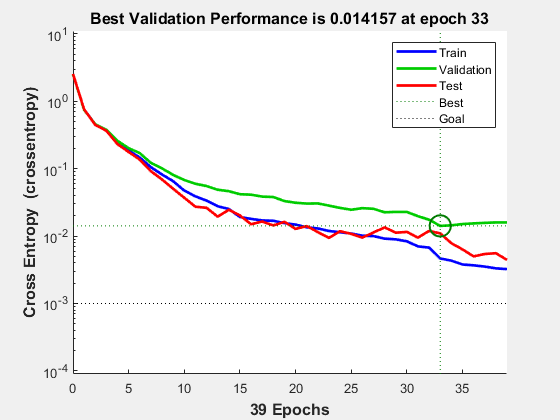

plotperform(tr);%plot performance graph

f) Test the trained net using testing dataset and evaluate its performance (e.g. classifier accuracy and recall rate). You may run several times for training and testing to get an average performance value. Why does each run has different results?

predictedData = net(testingData);
% perp = perform(net, testingTarget, predictedData);
% disp(perp);
% predictedData.t
predictedData

predictedData =     0.9984    0.0151    1.0000    1.0000    0.0000    0.9996    0.0000    0.0000    0.2939    0.0000    0.0000    0.0000    0.9734    0.0010    0.0000    1.0000    1.0000    0.9997    0.9998    0.0000    1.0000    0.0003    1.0000    0.8125    0.9983    1.0000    1.0000    1.0000    0.0000    0.0000    0.0000    0.9983    1.0000    0.0000    1.0000    0.0000    0.0000    0.0054    0.0425    0.0004    0.0000    1.0000    0.9996    0.0001    0.0000    1.0000    1.0000    0.0000    0.0000    0.0000


testingTarget

testingTarget =      1     0     1     1     0     1     0     0     0     0     0     0     1     0     0     1     1     1     1     0     1     0     1     1     1     1     1     1     0     0     0     1     1     0     1     0     0     0     0     0     0     1     1     0     0     1     1     0     0     0


%con = (testingTarget, predictedData);
%round arrays
roundedArray = round(predictedData)

roundedArray =      1     0     1     1     0     1     0     0     0     0     0     0     1     0     0     1     1     1     1     0     1     0     1     1     1     1     1     1     0     0     0     1     1     0     1     0     0     0     0     0     0     1     1     0     0     1     1     0     0     0


[val,pos]=intersect(testingTarget',roundedArray','rows');
val

val =      0
     1


pos

pos =      2
     1


%err = loss(net,predictedData,testingTarget);


g) Explore how neural network parameters (e.g. learning rate) and the number of neurons affect the performance of classifier. Explain what are normal stopping criteria for training.

%learningRates = [1,0.1, 0.01, 0.001, 0.0001]
% numOfNeurons = 0;
performances=[]


performances =

     []



for numOfNeurons = 1:1
    %select pattern net
    net = patternnet(numOfNeurons);
    
    % Not sure if these are correct parameter names
    net.trainParam.epochs = 50;
    net.trainParam.goal = 0.001;
    net.trainParam.lr = 0.1;

    [net, tr] = train(net, trainingData, trainingTargetData);
    
    predictedData = net(testingData);
    perf = perform(net, testingTarget, predictedData);
%     disp(perp);
%     tr
    performances(end + 1) = perf 
%     plotperform(tr);%plot performance graph
end

performances = 0.0557

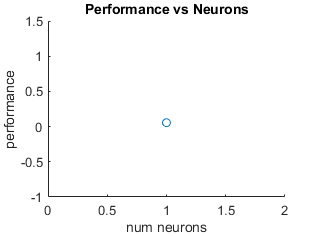

%change learning rate %%%
%%%
%%%
%%
figure
hold on
xlabel('num neurons')
ylabel('performance')
plot(performances,"o-")
title('Performance vs Neurons')
hold off

h) After completion of intrusion detector for just two classes (‘normal’ and ‘attack’), you now decide to further develop intrusion detection classifier for 3 classes (i.e. ‘normal’, DoS and probing attack), and 5 classes (i.e. ‘normal’, ‘smurf’, ‘neptune, ‘satan’ and ‘ipsweep’). What performance can you get for the intrusion detection classifier?

% dataset5 = fscanf("cw_dataset.txt")


% clear;
% fid = fopen('cw_dataset.txt','r');
% data = textscan(fid, '%s', 'Delimiter', '\n'); %read all data as string
% data = data{1};
% for i = 1:size(data,1)
%     nData{i,:} = strsplit(data{i},' '); %split data whitespace
%     if (mod(i,2)==1) %checks if uneven/POINT or even/PATH
%         nnData{i,1} = str2num(cell2mat(nData{i}(2))); %get POINT 1st number
%         nnData{i,2} = str2num(cell2mat(nData{i}(3))); %get POINT 2nd number
%     else
%         nnData{i,3} = str2num(cell2mat(nData{i}(2))); %get PATH 1st number
%     end
% end
% nnData = cell2mat(nnData); %make double matrix / removes empty rows
% fclose(fid);

dataset5 = load("cw_dataset.txt");

% shuffle data
selectRows = size(dataset5,1);
shuffle = randperm(selectRows);
shuffledDataset = dataset5(shuffle, :);
%transpose data
shuffledDataset = shuffledDataset';
[trainingDataset, validationDataset, testingDataset] = dividerand(shuffledDataset, 2/3, 0, 1/3);

trainingData = trainingDataset(1:41,:);
trainingTargetData = trainingDataset(42:46,:);

testingData = testingDataset(1:41,:);
testingTarget = testingDataset(42:46,:);

% Define the number of neurons
numOfNeurons = 10;

%select pattern net
net = patternnet(numOfNeurons);

% Define epoch, error goal and learning rate
epochs = 50;
errorGoal = 0.001;
learningRate = 0.1;

% Not sure if these are correct parameter names

net.trainParam.epochs = epochs;
net.trainParam.goal = errorGoal;
net.trainParam.lr = learningRate;

[net, tr] = train(net, trainingData, trainingTargetData);
view(net)

predictedData = net(testingData);
perp = perform(net, testingTarget, predictedData);
disp(perp);

    0.0398



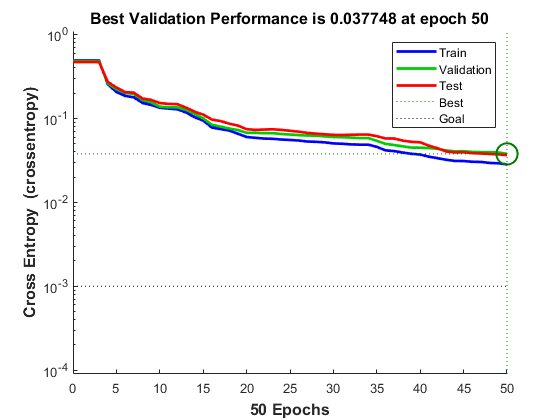

plotperform(tr);%plot performance graph